%Get user profile
userDir = getenv("USERPROFILE");

%Get the FLOATS directory for .mat files for calculating delta

%Load the BSL as a table
BSL = readtable(userDir+"\Documents\MATLAB\ARGO_PROCESSING\DATA\CAL\bad_sensor_list.TXT");
BSL_srt = sortrows(BSL,"WMO_","ascend"); %Sort by WMO's in ascending order to match floatsDir
BSL_ph= BSL_srt(contains(BSL_srt.SENSOR,"PH"),:); %Isolate lines with PH
BSL_ph_fail = BSL_ph(BSL_ph.FLAG==4,:); %Isolate PH flagged as fail (4)
%Create new column with all bad cycle numbers as doubles
BSL_ph_fail.BADCYCLENUM = cellfun(@str2double, regexp(BSL_ph_fail.CYCLES,'\d+','match'), "UniformOutput",false);

%Create txt file to log bad cycles from BSL and realtime qc algorithm
ph_log = fopen(userDir+"\Documents\realtime_ph_qc\realtimePH.TXT",'w');
fprintf(ph_log, '%s\t%s\t%s\n', "WMO", "bad_cycles", "est_bad_cycles"); %Populate column names

% BEGIN LOOP
for f = 1:10%length(floatsDir)

    [a, MSGID] = lastwarn();
    warning('off', MSGID)
    
    %Call float WMO from FLOATS directory
    wmoID = BSL_ph_fail.WMO_(f)
    wmoDir = dir(userDir+"\Documents\MATLAB\ARGO_PROCESSING\DATA\FLOATS\"+wmoID); %Load WMO directory
    wmoTable = struct2table(wmoDir); %Convert to table for easy indexing
    firstFile = 3; %First .mat file always starts on 3
    lastFile = length(find(~contains(wmoTable.name,'cal'))); %Last file is the profile before calxxx file
    
    %Subsample the directory so only the profile files are included
    wmoDir = wmoDir(firstFile:lastFile,:);
    
    %Initialize empty matrix to store points that go beyond delta threshold
    anomMat = double.empty(length(wmoDir),0); 
    anomCnt = 0;
    
    %Load in the floatViz data for the WMO
    floatVizDir = userDir+"\Documents\MATLAB\ARGO_PROCESSING\DATA\FLOATVIZ\QC\"+string(wmoID)+"QC.TXT";
    floatVizData = readtable(floatVizDir);
    
    %Subsample all good and failing ph, pressure, and station number data
    %at 1500m for future plots
    pH_qc = floatVizData.pHinsitu_Total_((floatVizData.QF_12==0|floatVizData.QF_12==8));
    pres_qc = floatVizData.Pressure_dbar_((floatVizData.QF_12==0|floatVizData.QF_12==8));
    stn_qc = floatVizData.Station((floatVizData.QF_12==0|floatVizData.QF_12==8));
    ph1500 = pH_qc(pres_qc<=1520 & pres_qc>=1480);
    stn1500 = stn_qc(pres_qc<=1520 & pres_qc>=1480);
    
    %Cycle through all .mat files in the directory up to the
    %second-to-last profile
    for i=1:length(wmoDir)-1
        
        %Load the "current" profile and subsample data point at 1500m
        currentProf = load ([wmoDir(1).folder,'\',wmoDir(i+1).name]);
        currentPH = currentProf.LR.PH_IN_SITU_TOTAL(currentProf.LR.PRES>=1480 & ...
            currentProf.LR.PRES<=1520);
        
        %Do the same for the profile before
        prevProf = load ([wmoDir(1).folder,'\',wmoDir(i).name]);
        prevPH = prevProf.LR.PH_IN_SITU_TOTAL(prevProf.LR.PRES>=1480 & ...
            prevProf.LR.PRES<=1520);
        
        %Find the difference between the two
        delta = abs(currentPH-prevPH);
        
        %SET DELTA THRESHOLD HERE
        if delta >= .005 %If delta goes over threshold, increase anomaly counter by 1
            anomCnt = anomCnt + 1;
            anomMat(i,1) = anomCnt;
        else %Otherwise reset anomaly counter back to 0
            anomCnt = 0;
            anomMat(i,1) = anomCnt;
        end
    end

    %Estimate the bad cycle based on the anomaly counter reaching 3,
    %then choose the cycle just before that data point
    estBadCycle = find(anomMat == 3)-1;

    %Use the floatViz data to isolate the data at the estimated bad cycle
    EstBadProf = floatVizData(floatVizData.Station==estBadCycle(1),:);
    
    %Do the same using the bad cycles marked in the BSL
    BadProf = floatVizData(floatVizData.Station==BSL_ph_fail.BADCYCLENUM{f}(end),:);

    fprintf(ph_log, '%d\t%d\t%d\n', wmoID, BSL_ph_fail.BADCYCLENUM{f}(end), estBadCycle(1));

    %Attempt to make the plots as well
    
    fig = figure;
    set(fig,'Visible','off')

    % Plot pH profiles with the bad cycle marked in red
    subplot(2,2,[1,3]);
    scatter(pH_qc, pres_qc, 8, stn_qc, 'filled');
    hold on;
    scatter(BadProf.pHinsitu_Total_,BadProf.Pressure_dbar_, 20,'k','filled');
    hold on;
    scatter(EstBadProf.pHinsitu_Total_,EstBadProf.Pressure_dbar_, 10,'r','filled');
    set(gca, 'YDir','reverse');
    set(gca, 'xlim',[4 8.5]);
    set(gca, 'ylim',[0 2000]);
    set(gca,'TickDir','out');
    title("pH Profiles");
    ylabel("Pressure [dbar]");
    xlabel("pH");
    c = colorbar;
    c.Label.String = 'Profile #';
    c.Label.FontSize = 10;
    c.Label.Rotation = -90;
    
    %Plot pH at 1500m
    subplot(2,2,2);
    plot(stn1500,ph1500,"b.-",'LineWidth',1,'MarkerSize',10);
    xline(BSL_ph_fail.BADCYCLENUM{f}(end), 'k-');
    xline(estBadCycle(1), '--r');
    %set(gca, 'ylim',[7.8 8.1]);
    set(gca,'TickDir','out');
    title("pH (@1500m)");
    ylabel("pH");
    xlabel("Station number");
    
    %Plot the difference in pH per cycle
    subplot(2,2,4);
    plot(stn1500(2:end),diff(ph1500),"b.-",'LineWidth',1,'MarkerSize',10);
    set(gca, 'ylim',[-.05 .05]);
    xline(BSL_ph_fail.BADCYCLENUM{f}(end), 'k-');
    xline(estBadCycle(1), '--r');
    yline([.005 -.005], '--k');
    set(gca,'TickDir','out');
    title("pH delta (@1500m)");
    ylabel("pH");
    xlabel("Station number");
    
    saveas(fig, userDir+"\Documents\realtime_ph_qc\"+string(wmoID)+".png");

end

wmoID = 1902303

wmoID = 1902304

wmoID = 1902380

wmoID = 1902381

wmoID = 1902382

wmoID = 1902383

wmoID = 1902385

wmoID = 1902454

wmoID = 1902457

wmoID = 1902648

fclose(ph_log);


wmoID = 1902383;
% badCycle = 70;

%wmoID = 1902303;
% badCycle = 43;

% wmoID = 4903365;
% badCycle = 96;

% wmoID = 4903485;
% badCycle = 33;

% wmoID = 5906342;
%badCycle = 90;

userDir = getenv("USERPROFILE");

dataDir = userDir+"\Documents\MATLAB\ARGO_PROCESSING\DATA\FLOATVIZ\QC\"+string(wmoID)+"QC.TXT";
data_sorted = readtable(dataDir);
%data_sorted = sortrows(Data,["Station" "Pressure_dbar_"],"ascend");

BSL = readtable(userDir+"\Documents\MATLAB\ARGO_PROCESSING\DATA\CAL\bad_sensor_list.TXT");
BSL_srt = sortrows(BSL,"WMO_","ascend");
BSL_ph= BSL_srt(contains(BSL_srt.SENSOR,"PH"),:);
BSL_ph_fail = BSL_ph(BSL_ph.FLAG==4,:);
BSL_ph_fail.BADCYCLENUM = cellfun(@str2double, regexp(BSL_ph_fail.CYCLES,'\d+','match'), "UniformOutput",false);
badCycle = BSL_ph_fail.BADCYCLENUM(BSL_ph_fail.WMO_==wmoID);

profList = dir(userDir+"\Documents\MATLAB\ARGO_PROCESSING\DATA\FLOATS\"+num2str(wmoID));
testTable = struct2table(profList);
firstFile = 3;
lastFile = length(find(~contains(testTable.name,'cal')));
wmoDir = profList(firstFile:lastFile,:);

anomMat = double.empty(length(wmoDir)-1,0);
anomCnt = 0;

for i=1:length(wmoDir)-1
    currentProf = load ([wmoDir(1).folder,'\',wmoDir(i+1).name]);
    currentPH = currentProf.LR.PH_IN_SITU_TOTAL_ADJUSTED(currentProf.LR.PRES>=1400 & ...
        currentProf.LR.PRES<=1600);
    
    prevProf = load ([wmoDir(1).folder,'\',wmoDir(i).name]);
    prevPH = prevProf.LR.PH_IN_SITU_TOTAL_ADJUSTED(prevProf.LR.PRES>=1400 & ...
        prevProf.LR.PRES<=1600);

    delta = abs(mean(currentPH)-mean(prevPH));
  
    if delta >= .0075 %Bigger delta means more leniency
        anomCnt = anomCnt + 1;
        anomMat(i,1) = anomCnt;
    else
        anomCnt = 0;
        anomMat(i,1) = anomCnt;
    end
end

estBadCycle = find(anomMat == 4)-3;
EstBadProf = data_sorted(data_sorted.Station==estBadCycle,:);

pH_qc = data_sorted.pHinsitu_Total_((data_sorted.QF_12==0|data_sorted.QF_12==8)&data_sorted.pHinsitu_Total_>0);
pres_qc = data_sorted.Pressure_dbar_((data_sorted.QF_12==0|data_sorted.QF_12==8)&data_sorted.pHinsitu_Total_>0);
stn_qc = data_sorted.Station((data_sorted.QF_12==0|data_sorted.QF_12==8)&data_sorted.pHinsitu_Total_>0);
ph1500 = pH_qc(pres_qc<=1520 & pres_qc>=1480);
stn1500 = stn_qc(pres_qc<=1520 & pres_qc>=1480);
BadProf = data_sorted(data_sorted.Station==badCycle{:},:);

f = figure;

% Plot pH profiles with the bad cycle marked in red
subplot(2,2,[1,3]);
scatter(pH_qc, pres_qc, 8, stn_qc, 'filled')
hold on
scatter(BadProf.pHinsitu_Total_,BadProf.Pressure_dbar_, 16,'k','filled')
hold on
scatter(EstBadProf.pHinsitu_Total_,EstBadProf.Pressure_dbar_, 10,'r','filled')
set(gca, 'YDir','reverse');
set(gca, 'xlim',[4 8.5]);
set(gca, 'ylim',[0 2000]);
set(gca,'TickDir','out');
title("pH Profiles");
ylabel("Pressure [dbar]");
xlabel("pH");
c = colorbar;
c.Label.String = 'Profile #';
c.Label.FontSize = 10

c =   ColorBar (Profile #) with properties:

    Location: 'eastoutside'
      Limits: [1 88]
    FontSize: 7.6500
    Position: [0.3832 0.1095 0.0239 0.8143]
       Units: 'normalized'

  Show all properties


c.Label.Rotation = -90

c =   ColorBar (Profile #) with properties:

    Location: 'eastoutside'
      Limits: [1 88]
    FontSize: 7.6500
    Position: [0.3832 0.1095 0.0239 0.8143]
       Units: 'normalized'

  Show all properties



%Plot pH at 1500m
subplot(2,2,2);
plot(stn1500,ph1500,"b.-",...
    'LineWidth',1, ...
    'MarkerSize',10)
xline(badCycle{:}, 'k-')
xline(estBadCycle, '--r')
set(gca, 'ylim',[7.8 8.1]);
set(gca,'TickDir','out');
title("pH (@1500m)");
ylabel("pH");
xlabel("Station number");

%Plot the difference in pH per cycle
subplot(2,2,4);
plot(stn1500(2:end),diff(ph1500),"b.-",...
    'LineWidth',1, ...
    'MarkerSize',10)
set(gca, 'ylim',[-.05 .05]);
xline(badCycle{:}, 'k-')
xline(estBadCycle, '--r')
yline([.005 -.005], '--k')
set(gca,'TickDir','out');
title("pH delta (@1500m)");
ylabel("pH");
xlabel("Station number");

savefig(f, [userDir,'\Documents\testPlot.fig']);

cycleDat = readtable ("C:\Users\lgrady\Documents\realtime_ph_qc\realtimePH.TXT")

cycleDat = 249×3 table
       WMO        bad_cycles    est_bad_cycles
    __________    __________    ______________

    1.9023e+06        43              45      
    1.9023e+06        29              52      
    1.9024e+06         1              18      
    1.9024e+06        70              71      
    1.9024e+06         1              11      
    1.9024e+06        70              72      
    1.9024e+06        41              43      
    1.9025e+06         1               2      
    1.9025e+06         2             NaN      
    1.9026e+06         1             NaN      
    2.9035e+06         1               2      
    2.9035e+06         1               2      
    2.9035e+06         1               2      
    2.9035e+06         1               9      
    2.9035e+06         4               4      
    2.9035e+06        17               6      



deltaDat = cycleDat.bad_cycles - cycleDat.est_bad_cycles

deltaDat =     -2
   -23
   -17
    -1
   -10
    -2
    -2
    -1
   NaN
   NaN


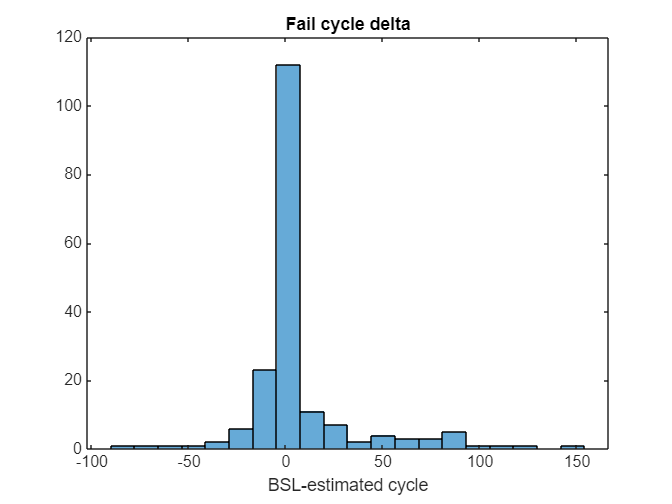


figure;
histogram(deltaDat, 20);
title("Fail cycle delta");
xlabel("BSL-estimated cycle");